## Initialize the FMCW Radar Computations

clear;
simulator = Simulator_revA();
%setup the victim's chirp parameters

simulator.load_B210_victim_params_lowBW;
simulator.load_B210_attacker_params_lowBW;

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 5.00 GHz
	 Frequency Slope: 		 1.00 MHz/us
	 Idle Time: 			 18.44 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.56 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.20 MSps
	 Ramp End Time: 		 26.56 us
	 Chirp Tx Bandwidth: 		 26.56 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 20.00 us
	 Chirp Cycle Time: 		 45.00 us
	 Chirp Wavelength: 		 59.96 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 11.52 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 479.67 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 333.10 m/s
	 Velocity Resolution 		 2.60 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 28.80 MHz
	 Downsampling factor 		 9
	 Sweep time 			 26.56 us


## Configure the Tx Data File

%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/chirp_full.bin";
fileID = fopen(path,'w');
data = double(simulator.Victim.chirp);
fwrite(fileID,reshape([real(data),imag(data)].',[],1), 'float32');
fclose(fileID);

## Plot Tx Chirp to confirm correctness

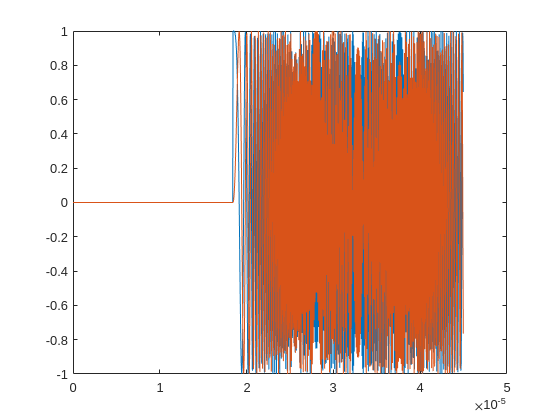

%plot the chirp signal
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.ChirpCycleTime_us * 1e-6 - ...
    simulator.Victim.FMCW_sampling_period_s;
plot(t,real(data),t,imag(data))

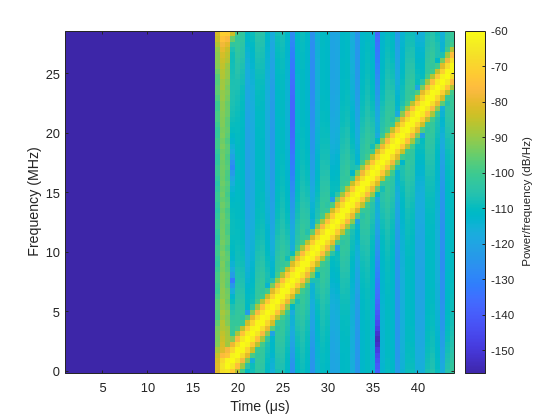

spectrogram(data,64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

## Read the Rx Data File

%to open a file from the GNU radio saved to a binary file
num_rows = 4;
num_cols = 5;
path = "/home/david/Documents/MATLAB_generated/write.bin";
fileID = fopen(path,'r');
read_data = fread(fileID,'float');
read_data = reshape(read_data,2,[]).';
read_data = read_data(:,1) + 1j * read_data(:,2);

%reshape the data into the correct format
read_data = pagetranspose(reshape(read_data,5,4,[]));
%disp(read_data);
fclose(fileID);